# Test Unstable Manifold

## parameters

clear
mMoon =7.348e22;% kg
mEarth = 5.9742e24; %kg
mu = mMoon/(mMoon + mEarth)

mu = 0.0122

## L1 unstable manifold


%periodo = 3.205884;
%X0 = [0.803317447531650 0 0 0.333418984453424]
X0 = [0.814947447531650 0 0 0.218592831633926];
periodo = 2.86510953884556;

C1 = jacobiConstant(X0(1,1:2),X0(1,3:4),mu)

C1 = 3.1516

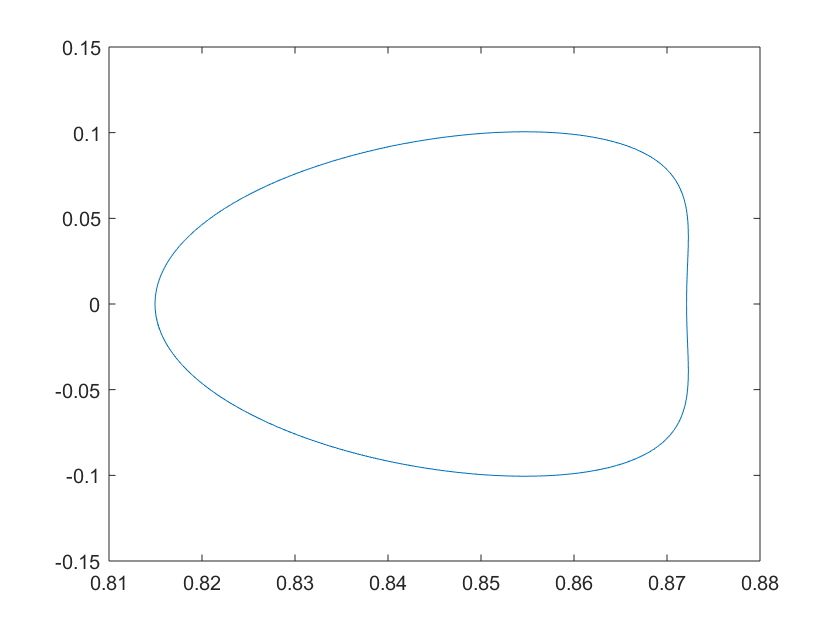

STM = reshape(eye(4),16,[])';
X = [X0 STM]';

%%% plot periodic orbit
numSteps=300;
tspan=linspace(0,periodo,numSteps);
ode__opt = odeset('RelTol',1e-13,'AbsTol',1e-22);
[t, X_periodica] = ode113(@CRTBPLyapunov, tspan,X , ode__opt, mu); 
plot(X_periodica(:,1),X_periodica(:,2))

figure

k = 200

k = 200

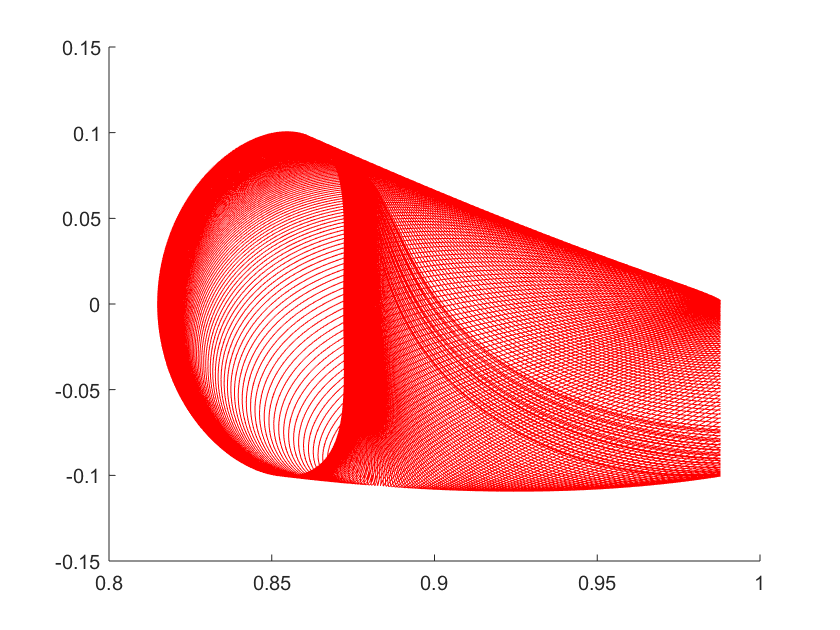

h = 1

epsilon=1e-6;
X_mainfold = calculateUnStableMainfold(periodo,X,mu,k,epsilon,1,true);


%% comprobar que manifold esta bien
%epsilon=1e-16;
%X_mainfold = calculateUnStableMainfold(periodo,X,mu,k,epsilon,true);


## L2 unstable manifold

hold on

%tFinalL2 = 4.6065
%[1.2299 0 0 -0,454910328634863]
%k = 40;
%periodo = 4.2454;
%X0 = [1.19878035065113	0	0	-0.308573433311396];
%STM = reshape(eye(4),16,[])';
%X = [X0 STM]';
%L2 stable manifold
%calculateUnStableMainfold(periodo,X,mu,k,100);
